依赖[统一实验分析作图v18.0.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

DataSet=TransferLearning.FullCalcium;
HeatCalcium=UniExp.NtatsCellReplenish(DataSet.QueryNTATS(UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'TemplateHitMiss'),UniExp.Flags.dFdF0,1:24,UniExp.Flags.Median));

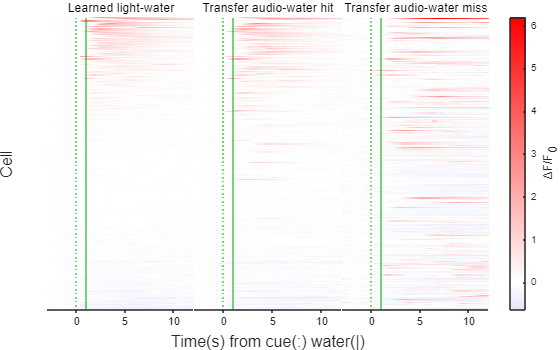

TemplateCalcium=HeatCalcium(ismember(HeatCalcium.CellUID,TransferLearning.TemplateCellUID(0.05,2)),:);
Colors=GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]);
NtatsData=UniExp.HeatmapSort(TemplateCalcium,"Learned_light_water").NTATS{:,:,["Learned_light_water","Transfer_audio_water_hit","Transfer_audio_water_miss"]};
SubTitles=["Learned light-water","Transfer audio-water hit","Transfer audio-water miss"];
HeatmapLayout=TransferLearning.BasicHeatmap(NtatsData,SubTitles,Colors,false);
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);

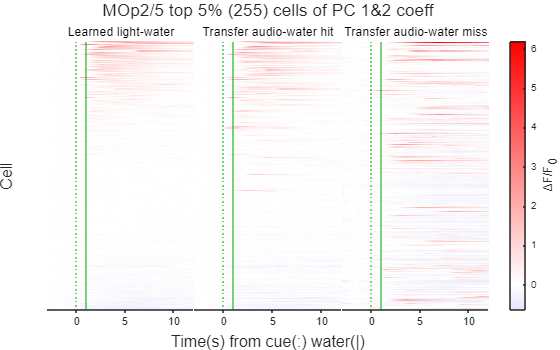

title(HeatmapLayout,sprintf('MOp2/5 top 5%% (%u) cells of PC 1&2 coeff',height(TemplateCalcium)));
print(TransferLearning.ProjectPath('TemplateHitMiss.svg'),'-dsvg');

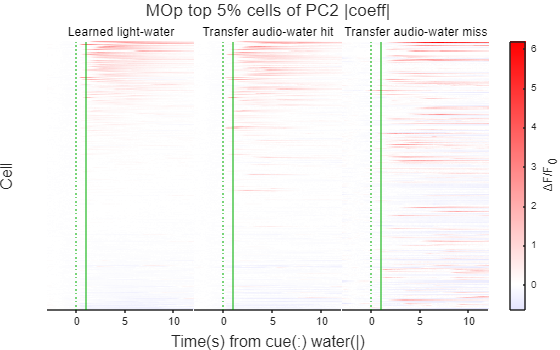

title(HeatmapLayout,'MOp top 5% cells of PC2 |coeff|');
print(TransferLearning.ProjectPath('TemplateHitMiss.PPT.svg'),'-dsvg');

[Mean,Sem]=MATLAB.DataFun.MeanSem(NtatsData,1);
Xs=linspace(-3,12,size(Mean,2))';

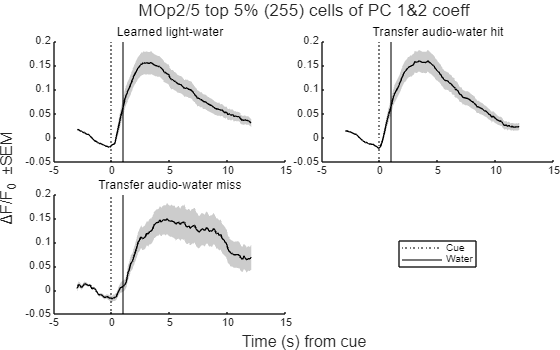

figure;
CurveLayout=tiledlayout(2,2,TileSpacing='tight',Padding='tight');
Axes=gobjects(3,1);
for A=1:3
	Axes(A)=nexttile;
	MATLAB.Graphics.MultiShadowedLines(Mean(:,:,A)',Sem(:,:,A)',X=Xs);
	CueLine=xline(0,':k');
	WaterLine=xline(1,'-k');
	title(SubTitles(A));
end
L=legend([CueLine,WaterLine],["Cue","Water"]);
L.Layout.Tile=4;
title(CurveLayout,sprintf('MOp2/5 top 5%% (%u) cells of PC 1&2 coeff',height(TemplateCalcium)));
ylabel(CurveLayout,'ΔF/F_0 ±SEM');
xlabel(CurveLayout,'Time (s) from cue');
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
MATLAB.UnifyYLims(Axes);
print(TransferLearning.ProjectPath('TemplateHitMissCurve.svg'),'-dsvg');